# Delft3D IO Module

The following example will familiarize the user with using the Delft3D (`delft_3d`) module in MHKiT-MATLAB. `delft_3d` can be used to plot the data from a NetCDF output from [Delft3D SNL-D3D-CEC-FM](https://github.com/sandialabs/SNL-Delft3D-CEC). The example will walk through a flume case with a turbine. The flume is 18 m long, 4 m wide and 2m deep with the turbine placed at 6 m along the length and 3 m along the width. The turbine used for this simulation has a circular cross-section with a diameter of 0.7m, a thrust coefficient of 0.72, and a power coefficient of 0.45. The simulation was run with 5 depth layers and 5-time intervals over 4 min.

This example will show how to create a centerline plot at a desired depth for different variables outputs of Delft3D. It will also show how to make a contour plot of a given plane or depth for the variable output by Delft3D and how to use those variables to calculate turbulence intensity. This module can be helpful to visualize the wake of a turbine and help predict how a turbine will affect the surrounding area.

## Loading Data from Delft3D as NetCDF

A NetCDF file has been saved in the [MHKiT-MATLAB\examples\data\river\d3d](https://github.com/MHKiT-Software/MHKiT-MATLAB/examples/river/d3d) directory of a simple flume case with a turbine for reference data. In this code section we define the location of the Delft 3D output NetCDF file and read the file into `delft_3d_turbine_test`

Opening file:

delft_3d_turbine_test_file = "examples/data/river/d3d/turbineTest_map.nc";
data = delft_3d_open_netcdf(delft_3d_turbine_test_file);

There are many variables saved in within the Delft3D NetCDF . The function `get_delft_3d_keys` returns a struct of the available data. Here we display the struct to see all the variables.

Displaying the values in the input Delft3D file:

turbine_test_structure = delft_3d_get_keys(data);
disp(turbine_test_structure);

                   mesh2d_enc_x: 'x-coordinate'
                   mesh2d_enc_y: 'y-coordinate'
          mesh2d_enc_node_count: 'count of coordinates in each instance geometry'
     mesh2d_enc_part_node_count: 'count of nodes in each geometry part'
       mesh2d_enc_interior_ring: 'type of each geometry part'
     mesh2d_enclosure_container: ''
                         Mesh2D: ''
                      NetNode_x: 'x-coordinate'
                      NetNode_y: 'y-coordinate'
    projected_coordinate_system: ''
                      NetNode_z: 'bed level at net nodes (flow element corners)'
                        NetLink: 'link between two netnodes'
                    NetLinkType: 'type of netlink'
                    NetElemNode: 'mapping from net cell to net nodes (counterclockwise)'
                    NetElemLink: 'mapping from net cell to its net links (counterclockwise)'
               NetLinkContour_x: 'list of x-contour points of momentum control volume surrounding each net/fl

## Seconds Run and Time Index

The `time_index` can be used to pull data from different instances in time. For the example data included there are 5-time steps meaning we have indexes in the range 0 and to 4. Each time index has an associated `seconds_run` that quantifies the number of seconds that passed from the start of the simulation. To get all of the `seconds_run` for a data set use the function `get_all_time` the output is an array of all the `seconds_run` for the input data set.

time = delft_3d_get_all_time(data);
disp(time);

     0    60   120   180   240



To convert from a `seconds_run` to a `time_index` or vice versa. The inputs are a netcdf data set, then a `time_index`. This example shows what happens if you input a `seconds_run` that is close to but not exactly a `seconds_run` associated with a `time_index`. The function will throw a warning and return the closest time index.

seconds_run = 62;
time_index = delft_3d_convert_time(data, seconds_run);
display(time_index);

time_index = 2

We can then use that index to get the associated time value:

closest_time = time(time_index)

closest_time = 60

# Struct From NetCDF

For this example we will create a MATLAB struct from the D3d NetCDF object using the variable 'ucx', the velocity in the x-direction (see available data in previous block output). MHKiT MATLAB's `delft_3d_get_all_data_points` function will pull all the raw data from the NetCDF file for the specified variable at a specific time index in a dataframe var_data_df. The time_index can be used to pull data from a different instances in time (the last valid time_index, time_index=-1, is the default setting). If an integer outside of the valid range is entered the code will output an error with the max valid output listed. The output data from get_all_data_points will be the position (x, y, waterdepth) in meters, the value of vairable in meters per second and the run time of the simulation in seconds or 'x', 'y', 'waterdepth', 'waterlevel', 'ucx', and 'time'. The time run in simulation varies based on the 'time_step'.

In MHKiT-MATLAB we return a structure containg the results including the MHKiT-Python generated DataFrame under the `df` key.

% Getting variable data
x_velocity_key = "ucx";
run_timestamps = delft_3d_get_all_time(data);
seconds_into_simulation = run_timestamps(1, 4);
seconds_into_simulation_index = delft_3d_convert_time(data, seconds_into_simulation);

x_velocity_point_data = delft_3d_get_all_data_points(data, x_velocity_key, seconds_into_simulation_index);

disp(x_velocity_point_data);

             x: [0.1250 0.3750 0.1250 0.6250 0.3750 0.1250 0.8750 0.6250 0.3750 0.1250 1.1250 0.8750 0.6250 0.3750 0.1250 1.3750 1.1250 0.8750 0.6250 0.3750 0.1250 1.6250 1.3750 1.1250 0.8750 0.6250 0.3750 0.1250 1.8750 1.6250 1.3750 … ] (1×5760 double)
             y: [1.1250 1.1250 1.3750 1.1250 1.3750 1.6250 1.1250 1.3750 1.6250 1.8750 1.1250 1.3750 1.6250 1.8750 2.1250 1.1250 1.3750 1.6250 1.8750 2.1250 2.3750 1.1250 1.3750 1.6250 1.8750 2.1250 2.3750 2.6250 1.1250 1.3750 1.6250 … ] (1×5760 double)
    waterdepth: [0.1995 0.2000 0.1995 0.2001 0.2000 0.1995 0.2001 0.2001 0.2000 0.1995 0.2000 0.2001 0.2001 0.2000 0.1995 0.2000 0.2000 0.2001 0.2001 0.2000 0.1995 0.2000 0.2000 0.2000 0.2001 0.2001 0.2000 0.1995 0.2000 0.2000 0.2000 … ] (1×5760 double)
    waterlevel: [-0.0052 8.1291e-05 -0.0052 5.5880e-04 8.1324e-05 -0.0052 5.0091e-04 5.5884e-04 8.1385e-05 -0.0052 4.4621e-04 5.0097e-04 5.5892e-04 8.1465e-05 -0.0052 3.8288e-04 4.4630e-04 5.0108e-04 5.5902e-04 8.1552e-05 -0.0052 … ] (1×5

The limits max_plot_vel and min_plot_vel are defined to bound the plots of the variable's data in the next 3 example plots.

% Setting plot limits
max_plot_vel = 1.25;
min_plot_vel = 0.5;

# Plotting a Line Plot Between Two Points

To view the maximum wake effect of the turbine we can plot a velocity down the centerline of the flume. To do this we will create an array between two points down the center of the flume. We will then interpolate the grided data results onto our centerline array. Since the flume is retangular the centerline points are found by taking the average of the maximum and minimum value for the width, y, and the waterdepth, of the flume. We will then input one array, x, and two points, y and waterdepth into the function create_points to create our centerline array to interpolate over. The function create_points will then output a dataframe, cline_points, with keys 'x', 'y', and 'waterdepth'.

% Use rectangular grid min and max to find flume centerline
xmax = min(x_velocity_point_data.x);
xmin = max(x_velocity_point_data.x);

ymax = min(x_velocity_point_data.y);
ymin = max(x_velocity_point_data.y);

waterdepth_max = min(x_velocity_point_data.waterdepth);
waterdepth_min = max(x_velocity_point_data.waterdepth);

x = linspace(xmin, xmax, 50); % 50 is the numpy default
y = mean([ymax, ymin]);
waterdepth = mean([waterdepth_max, waterdepth_min]);

cline_points = delft_3d_create_points(x, y, waterdepth);
disp(cline_points);

             x: [17.8750 17.5128 17.1505 16.7883 16.4260 16.0638 15.7015 15.3393 14.9770 14.6148 14.2526 13.8903 13.5281 13.1658 12.8036 12.4413 12.0791 11.7168 11.3546 10.9923 10.6301 10.2679 9.9056 9.5434 9.1811 8.8189 8.4566 8.0944 … ] (1×50 double)
             y: [3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3]
    waterdepth: [1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 … ] (1×50 double)
            df: [1×1 py.pandas.core.frame.DataFrame]



points = [x_velocity_point_data.x; x_velocity_point_data.y; x_velocity_point_data.waterdepth];
values = x_velocity_point_data.(x_velocity_key);
xi = [cline_points.x; cline_points.y; cline_points.waterdepth];

cline_variable = delft_3d_interpolate_to_centerline(points, values, xi);
disp(cline_variable);

    0.9813    0.9819    0.9799    0.9782    0.9759    0.9736    0.9710    0.9684    0.9656    0.9627    0.9596    0.9564    0.9531    0.9496    0.9460    0.9421    0.9380    0.9337    0.9291    0.9242    0.9189    0.9132    0.9069    0.9001    0.8926    0.8842    0.8748    0.8643    0.8522    0.8388    0.8229    0.8040    0.7882    0.8789    1.0675    1.0586    1.0608    1.0619    1.0620    1.0619    1.0616    1.0611    1.0607    1.0602    1.0597    1.0591    1.0586    1.0581    1.0590    1.0563



Next the variable ucx is interpolated onto the created cline_points using scipy interp function and saved as cline_variable. The results are then plotted for velocity in the x direction, ucx, along the length of the flume, x.

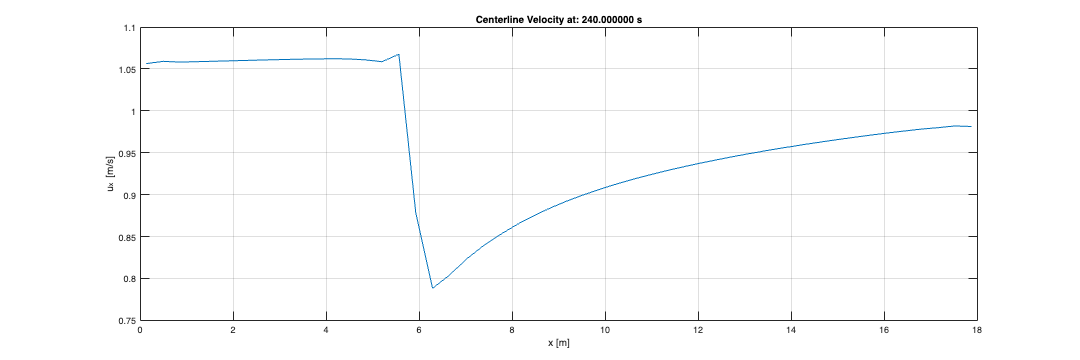

fig_width = 1200;
fig_height = 400;
figure('position', [0, 0, fig_width, fig_height]);
plot(x, cline_variable);
grid("on");
xlabel("x [m]")
ylabel("u_x [m/s]")
title(sprintf("Centerline Velocity at: %f s", x_velocity_point_data.time(1)))

## Contour Plot for a Given Sigma Layer

Sometimes it is useful to plot only the raw data of a given layer. Using get_layer_data a single layer of raw data will be retrieved from the NetCDF object. The d3d function ,get_layer_data takes 3 inputs, the NetCDF object (d3d_data), a variable name as a string (variable), and the layer to retrieve (layer) as an integer. The variable is set to the velocity in the x direction, 'ucx', and the layer of data to plot as 2. Since there are 5 sigma layers in this example layer 2 is approximately the middle layer. layer works as an index that begins at begins at 0 and ends at 4. The get_layer_data then outputs a dataframe layer_data with the keys 'x', 'y', 'waterdepth', 'waterlevel', 'v', and 'time' as the length, width, waterdepth, value, and run time of simulation of the specified variable in this case velocity in the x direction, 'ucx'.

To plot the data the maximum and minimum, max_plot_vel and min_plot_vel, values are pulled from above to limit bounds of the color bar to show the value of the specified variable, in this case it's velocity in the x direction. The type of plot is also defined as a string 'contour' to add to the title of the plot.

layer = 2;
layer_data = delft_3d_get_layer_data(data, x_velocity_key, layer);
disp(layer_data);

             x: [0.1250 0.3750 0.1250 0.6250 0.3750 0.1250 0.8750 0.6250 0.3750 0.1250 1.1250 0.8750 0.6250 0.3750 0.1250 1.3750 1.1250 0.8750 0.6250 0.3750 0.1250 1.6250 1.3750 1.1250 0.8750 0.6250 0.3750 0.1250 1.8750 1.6250 1.3750 … ] (1×1152 double)
             y: [1.1250 1.1250 1.3750 1.1250 1.3750 1.6250 1.1250 1.3750 1.6250 1.8750 1.1250 1.3750 1.6250 1.8750 2.1250 1.1250 1.3750 1.6250 1.8750 2.1250 2.3750 1.1250 1.3750 1.6250 1.8750 2.1250 2.3750 2.6250 1.1250 1.3750 1.6250 … ] (1×1152 double)
    waterdepth: [0.9974 1.0000 0.9974 1.0003 1.0000 0.9974 1.0003 1.0003 1.0000 0.9974 1.0002 1.0003 1.0003 1.0000 0.9974 1.0002 1.0002 1.0003 1.0003 1.0000 0.9974 1.0002 1.0002 1.0002 1.0003 1.0003 1.0000 0.9974 1.0001 1.0002 1.0002 … ] (1×1152 double)
    waterlevel: [-0.0052 8.1291e-05 -0.0052 5.5880e-04 8.1324e-05 -0.0052 5.0091e-04 5.5884e-04 8.1385e-05 -0.0052 4.4621e-04 5.0097e-04 5.5892e-04 8.1465e-05 -0.0052 3.8288e-04 4.4630e-04 5.0108e-04 5.5902e-04 8.1552e-05 -0.0052 … ] (1×1

[x_grid, y_grid] = meshgrid(linspace(min(layer_data.x), max(layer_data.x), 100), ...
                             linspace(min(layer_data.y), max(layer_data.y), 100));
v_interp = griddata(layer_data.x, layer_data.y, layer_data.v, x_grid, y_grid);

% Plot filled contours
figure('position', [0, 0, fig_width, fig_height])
contourf(x_grid, y_grid, v_interp, 10, 'LineStyle', 'none');
colorbar; % Add color bar
clim([min_plot_vel, max_plot_vel]); % Set color axis limits
colormap(viridis_colormap); % Set colormap (optional)
xlabel('x [m]');
ylabel('y [m]');
title(['Velocity on Layer ', num2str(layer), ' at Time: ', num2str(layer_data.time(1)), ' s']);

% Add units label to colorbar
h = colorbar;
ylabel(h, '$u_x$ [m/s]', 'Interpreter', 'latex');

## Plotting a Contour Plot of a given Plane

If you wanted to look at a contour plot of a specific waterdepth you can create a contour plot over given points. Expanding on the centerline array points we can create a grid using the same create_points function by inputting two arrays along the length of the flume, x , and width of the flume, y_contour , and one point for the waterdepth we want to look at. create_points then outputs a dataframe contour_points of points to calculate the contour values over with the keys 'x', 'y', and 'waterdepth'.

x2 = linspace(xmin, xmax, 100);
y_contour = linspace(ymin, ymax, 40);
z2 = mean([waterdepth_max, waterdepth_min]);

contour_points = delft_3d_create_points(x2, y_contour, z2);

[0, 1, 2]


display(contour_points);

contour_points = struct with fields:
             x: [17.8750 17.6957 17.5164 17.3371 17.1578 16.9785 16.7992 16.6199 16.4407 16.2614 16.0821 15.9028 15.7235 15.5442 15.3649 15.1856 15.0063 14.8270 14.6477 14.4684 14.2891 14.1098 13.9306 13.7513 13.5720 13.3927 13.2134 … ] (1×4000 double)
             y: [4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 … ] (1×4000 double)
    waterdepth: [1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 … ] (1×4000 double)
            df: [1×1 py.pandas.core.frame.DataFrame]


points = [x_velocity_point_data.x; x_velocity_point_data.y; x_velocity_point_data.waterdepth];
values = x_velocity_point_data.(x_velocity_key);
xi = [contour_points.x; contour_points.y; contour_points.waterdepth];

contour_variable = delft_3d_interpolate_to_centerline(points, values, xi);

The results are then plotted. The minimum and maximum values show on the graph are pulled from above (max_plot_vel and min_plot_vel) as in the previous example. The contour plot of the velocity is then output at the center waterdepth of the flume.

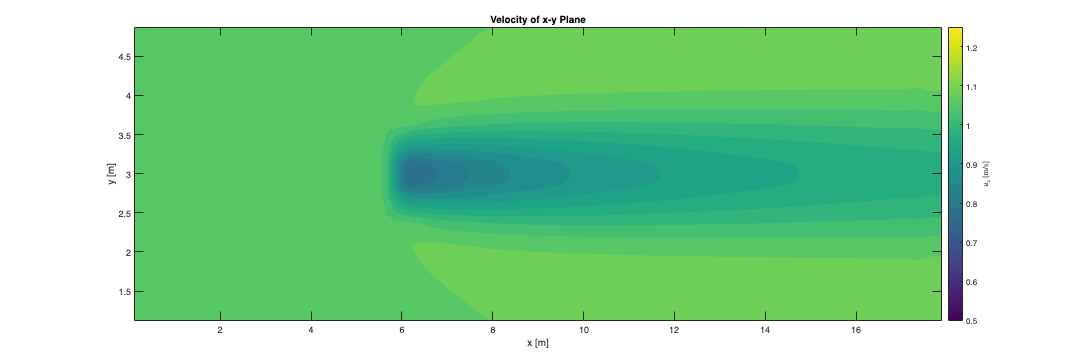


[x_grid, y_grid] = meshgrid(linspace(min(contour_points.x), max(contour_points.x), 100), ...
                             linspace(min(contour_points.y), max(contour_points.y), 100));
v_interp = griddata(contour_points.x, contour_points.y, contour_variable, x_grid, y_grid);

% Plot filled contours
figure('position', [0, 0, fig_width, fig_height])
contourf(x_grid, y_grid, v_interp, 10, 'LineStyle', 'none');
colorbar; % Add color bar
clim([min_plot_vel, max_plot_vel]); % Set color axis limits
colormap(viridis_colormap); % Set colormap (optional)
xlabel('x [m]');
ylabel('y [m]');
title("Velocity of x-y Plane");

% Add units label to colorbar
h = colorbar;
ylabel(h, '$u_x$ [m/s]', 'Interpreter', 'latex');

## Contour Plot of Turbulent Intensity

Turbulent Intensity is the ratio of the magnitude of turbulent velocity to total velocity. The function turbulent_intensity takes the inputs of the NetCDF object, the points to calculate over, the time index, and an optional boolean input to output intermediate_values used to calculate turbulent intensity. The fuction then pulls variables 'ucx', 'ucy', 'ucz', and 'turkin1' as the velocity in the x, y, waterdepth and turbulence kinetic energy respectively. The function then calculates and outputs the turbulent intensity, turbulent_intensity, for any given time_index in the data_frame TI. The TI dataframe also includes the x,y, and waterdepth location. If the intermediate_values bollian is equal to true the turbulent kinetic energy 'turkin1', and velocity in the 'ucx', 'ucy', and 'ucz' direction are also included.

In this example it is calculating the turbulent intensity over the same contour_points used above, however it can also calculate over 'cells', the coordinate system for the raw velocity data, or 'faces', the coordinate system for the raw turbulence data. If nothing is specified for points, 'cells' is the default coordinate system.

Following the same format as the previous two contour plots the limits of the maximum and minimum values are defined by user as well as a string for the type of plot. The code then outputs a contour plot of the turbulent intensity.

turbulent_intensity = delft_3d_calculate_turbulent_intensity(data, contour_points.df, true);

points provided


disp(turbulent_intensity);

                      x: [17.8750 17.6957 17.5164 17.3371 17.1578 16.9785 16.7992 16.6199 16.4407 16.2614 16.0821 15.9028 15.7235 15.5442 15.3649 15.1856 15.0063 14.8270 14.6477 14.4684 14.2891 14.1098 13.9306 13.7513 13.5720 13.3927 … ] (1×4000 double)
                      y: [4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 4.8750 … ] (1×4000 double)
             waterdepth: [1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 1.0009 … ] (1×4000 double)
                turkin1: [0.0031 0.0031 0.0031 0.0030 0.0030 0.0030 0.0031 0.0031 0.0031 0.0031 0.0031 0.0031 0.0031 0.0031 0.0031 0.0031 0.0031 0.0031 0.0031 0.0031 0.0031 0.0031 0.0031 0.0031 0.0030 0.0030 0.0030 0.0029 0.0029 0.002

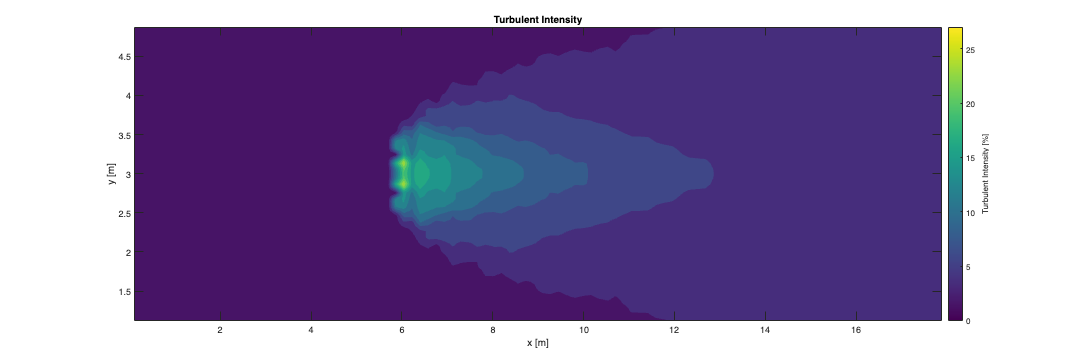

max_plot_ti = 27;
min_plot_ti = 0;

[x_grid, y_grid] = meshgrid(linspace(min(turbulent_intensity.x), max(turbulent_intensity.x), 100), ...
                             linspace(min(turbulent_intensity.y), max(turbulent_intensity.y), 100));
v_interp = griddata(turbulent_intensity.x, turbulent_intensity.y, turbulent_intensity.turbulent_intensity, x_grid, y_grid);

% Plot filled contours
figure('position', [0, 0, fig_width, fig_height]);
contourf(x_grid, y_grid, v_interp, 10, 'LineStyle', 'none');
colorbar; % Add color bar
clim([min_plot_ti, max_plot_ti]); % Set color axis limits
colormap(viridis_colormap); % Set colormap (optional)
xlabel('x [m]');
ylabel('y [m]');
title("Turbulent Intensity");

% Add units label to colorbar
h = colorbar;
ylabel(h, 'Turbulent Intensity [%]');

## Comparing Face Data to Cell Data

In Delft3D there is a staggered grid where some variables are stored on the faces and some are stored on the cells. The d3d.variable_interpolation function allows you to linearly interpolate face data onto the cell locations or vice versa. For this example, we input the variable names, 'ucx', 'ucy','ucz', and 'turkin1', which are pulled from the NetCDF object (d3d_data) and are to be interpolated on to the coordinate system 'faces'. The output is a data frame, Var, with the interpolated data.

Near the boundaries linear linterpolate will sometimes return negative values. When calculating turbulent intensity negative turbulent kinetic energy values (turkin1) will have and invalid answered. To filter out any negative values the index of where the negative numbers are located are calculated as neg_index. If the value is close to 0 (greater then -1.0e-4) the values is replaced with zero, if not it is replaced with nan. zero_bool determines if the negative number is close to 0. zero_ind is the location of the negative numbers to be replaced with zero and non_zero_bool are the locations of the numbers to replace with nan. To calculate turbulent intensity the magnitude of the velocity is calculated with 'ucx', 'ucy', 'ucz' and saved as u_mag.Turbulent intensity is then calculated with u_mag and turkin1 and saved as turbulent_intensity.

Linear interpolate can also leave nan values near the edges of data. If you want fill these in using nearest interpolate set the values edges to equal 'nearest' otherwis this option is dufalted to 'none'.

The data can be called, as shown, with Var. We now have 'ucx' and 'turkin1' on the same grid so then can be compared and used in calculations.

variables = {'turkin1', 'ucx', 'ucy', 'ucz'};

var_interpolation = delft_3d_calculate_variable_interpolation(data, variables, 'faces', 'nearest');

% Replacing negative numbers close to zero with zero
% neg_index = find(Var_struct.turkin1 < 0); % Finding negative numbers
% disp(neg_index);

% % Determining if negative numbers are close to zero 
% zero_bool = close(Var_struct.turkin1(Var_struct.turkin1 < 0), ...
    %zeros(1, sum(Var_struct.turkin1 < 0)), 'abstol', 1.0e-4);
%disp(zero_bool);
% 
% % Identifying the location of negative values close to zero 
%zero_ind = neg_index(zero_bool);
%disp(zero_ind);
% % Identifying the location of negative numbers that are not close to zero
% non_zero_ind = neg_index(~zero_bool);
% 
% % Replacing negative numbers close to zero with zero 
% Var_struct.turkin1(zero_ind) = zeros(1, length(zero_ind));
% 
% % Replacing negative numbers not close to zero with nan 
% Var_struct.turkin1(non_zero_ind) = NaN;
% 
% % Calculating the root mean squared velocity 
var_interpolation.u_mag = delft_3d_calculate_unorm(var_interpolation.ucx, var_interpolation.ucy, var_interpolation.ucz);


% Calculating turbulent intensity as a percent 
var_interpolation.turbulent_intensity = (sqrt(2/3 * var_interpolation.turkin1) ./ var_interpolation.u_mag) * 100;


When plotting data using d3d.variable_interpolation it is helpful to define points to interpolate onto as the 'cell' and 'face' grids contain a 3 dimensional grid of points. In this next example we will use the d3d.variable_interpolation function to plot a contour plot of tubulent intesity normal to turbine (y-waterdepth cross section) n turbine diameters downstream of the turbine.

As stated in the intro, the turbine is located at 6m along the length turbine_x_loc with a diameter of 0.7m (turbine_diameter). Similar to the previous example, we input the variable names variables 'ucx', 'ucy','ucz', and 'turkin1', which are pulled from the NetCDF object (d3d_data). Unlike the previous example, the points are defined as sample_points created using create_points from x_sample, y_sample, and waterdepth_sample with x_sample at a constant point of 1 (N) turbine diameters downstream of the turbine (6.7m) and y_sample and waterdepth_sample being arrays between the minimum and maximum values for that flume dimension. The interpolated data is the saved from d3d.variable_interpolation as Var_sampleand used to calculate turbulent intensity as in the previous example. The data is then plotted along the y and waterdepth axis.

turbine_x_loc = 6;
turbine_diameter = 0.7;
N = 1;
x_sample = turbine_x_loc + N * turbine_diameter;
y_samples = linspace(ymin, ymax, 40);
waterdepth_samples = linspace(waterdepth_min, waterdepth_max, 256);

variables = {'turkin1', 'ucx', 'ucy', 'ucz'};
sample_points = delft_3d_create_points(x_sample, y_samples, waterdepth_samples);

[0, 1, 2]


Var_sample = delft_3d_calculate_variable_interpolation(data, variables, sample_points.df, "nearest");

points provided


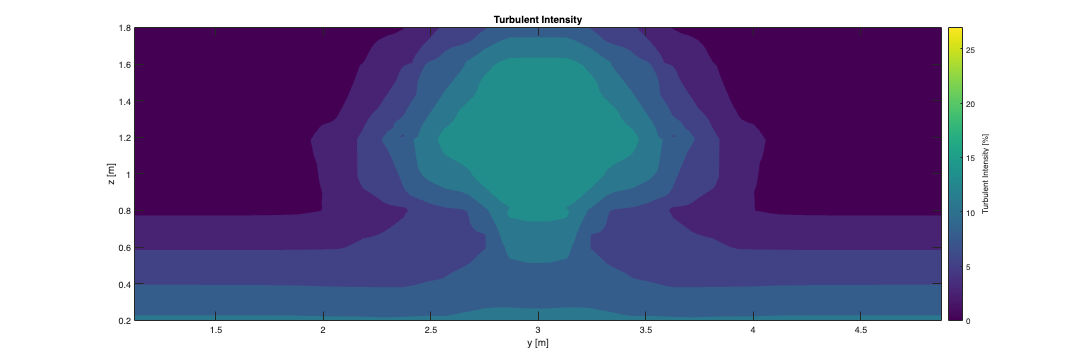

Var_sample.u_mag = delft_3d_calculate_unorm(Var_sample.ucx, Var_sample.ucy, Var_sample.ucz);
Var_sample.turbulent_intensity = sqrt(2/3 * Var_sample.turkin1) ./ Var_sample.u_mag * 100;

[x_grid, y_grid] = meshgrid(linspace(min(Var_sample.y), max(Var_sample.y), 100), ...
                             linspace(min(Var_sample.waterdepth), max(Var_sample.waterdepth), 100));
v_interp = griddata(Var_sample.y, Var_sample.waterdepth, Var_sample.turbulent_intensity, x_grid, y_grid);

% Plot filled contours
figure('position', [0, 0, fig_width, fig_height]);
contourf(x_grid, y_grid, v_interp, 5, 'LineStyle', 'none');
colorbar; % Add color bar
clim([min_plot_ti, max_plot_ti]); % Set color axis limits
colormap(viridis_colormap); % Set colormap (optional)
xlabel('y [m]');
ylabel('z [m]');
title("Turbulent Intensity");

% Add units label to colorbar
h = colorbar;
ylabel(h, 'Turbulent Intensity [%]');